% Requirement 7
%time in hrs
Vmax=3.7;
chargeRate=[.1, .2, .5, 1, 1.5, 2];
U=1;
R=0.1;
t=[0:0.001:1.5];
I=zeros(length(t),1);
V=zeros(length(t),1);
x=zeros(length(t),1);


I = 1 + 0.2*sin(0.01*3600*t)

I =     1.0000    1.0072    1.0144    1.0216    1.0287    1.0358    1.0429    1.0499    1.0568    1.0637    1.0705    1.0771    1.0837    1.0902    1.0966    1.1028    1.1089    1.1149    1.1207    1.1264    1.1319    1.1372    1.1424    1.1473    1.1521    1.1567    1.1610    1.1652    1.1692    1.1729    1.1764    1.1797    1.1827    1.1855    1.1881    1.1904    1.1925    1.1943    1.1959    1.1972    1.1983    1.1991    1.1997    1.1999    1.2000    1.1998    1.1993    1.1985    1.1975    1.1963


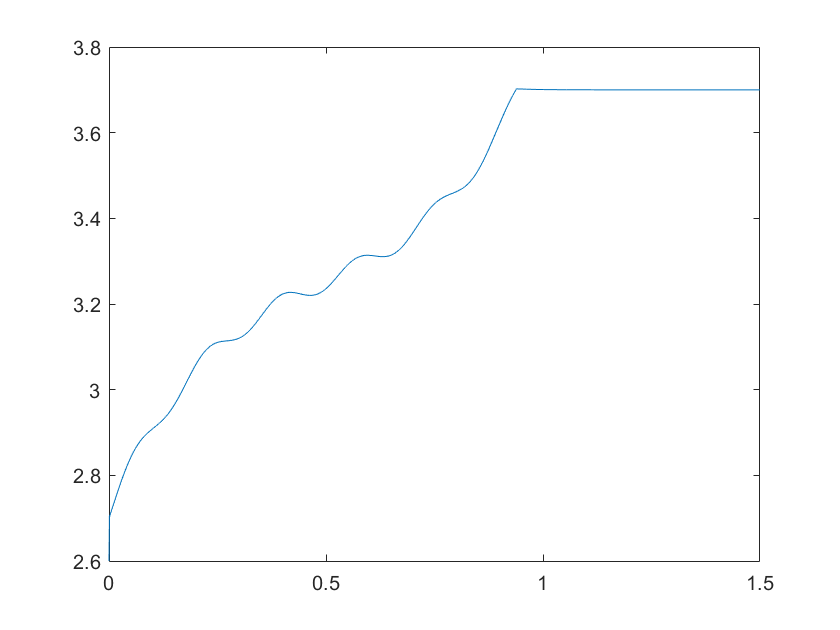



    V(1)=2.6;
    x(1)=0;
    I(1)=1;
    
    
    for i=2:length(t)
        I(i)=cccv(x(i-1),I(i),Vmax);
        x(i)=x(i-1)+(I(i)/1000);
        V(i)=(2.6+2.35*x(i)-3.75*x(i)^2+2.5*x(i)^3)+R*I(i);
        
    end
    
  plot(t, V)

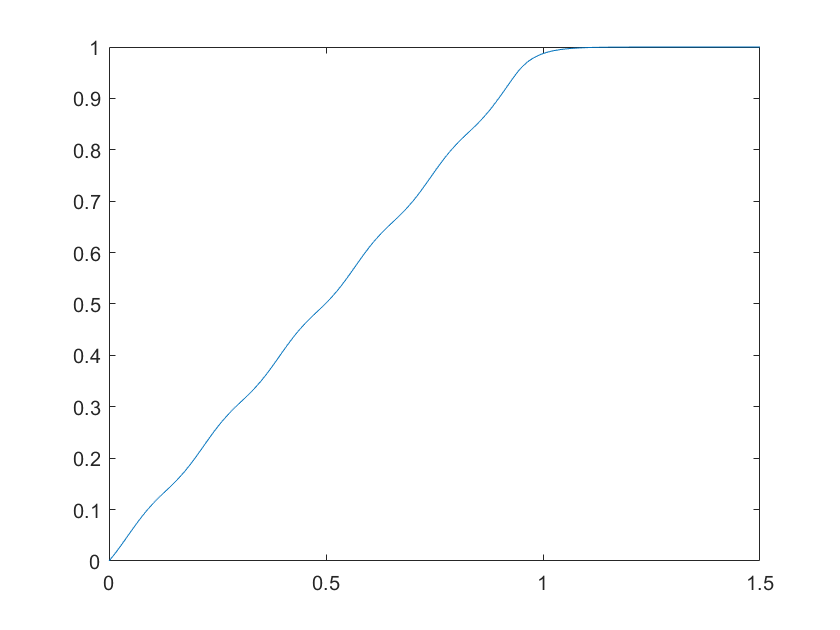

  plot(t, x)

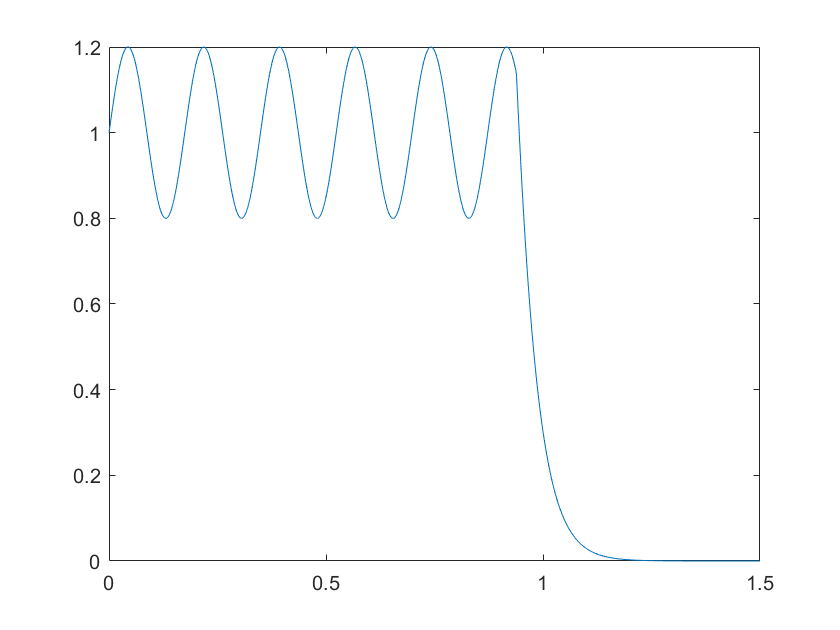

  plot(t,I)